% Définir les symboles pour les angles d'articulation
syms theta1 theta2 theta3 theta4;

% Définir les longueurs des bras
a1 = 2; % Longueur du premier bras
a2 = 3; % Longueur du deuxième bras
a3 = 2; % Longueur du troisième bras
a4 = 2; % Longueur du troisième bras
a5 = 2; % Longueur du troisième bras

% Définir la position désirée de l'effecteur
x_desired = 2;
y_desired = 5;


%ESPACE DE TRAVAIL
% Initialiser une liste pour stocker les coordonnées atteignables
reachable_points = [];

% Définir la grille d'angles d'articulation
theta1_range = linspace(-pi, pi, 12);
theta2_range = linspace(-pi, pi, 12);
theta3_range = linspace(-pi, pi, 12);
theta4_range = linspace(-pi, pi, 12);

% Calculer les coordonnées atteignables pour chaque combinaison d'angles
for i = 1:length(theta1_range)
    for j = 1:length(theta2_range)
        for k = 1:length(theta3_range)
            for l = 1:length(theta4_range)
                % Calculer les coordonnées de l'effecteur
                x = a1 * cos(theta1_range(i)) + a2 * cos(theta1_range(i) + theta2_range(j)) + a3 * cos(theta1_range(i) + theta2_range(j) + theta3_range(k) + theta4_range(l));
                y = a1 * sin(theta1_range(i)) + a2 * sin(theta1_range(i) + theta2_range(j)) + a3 * sin(theta1_range(i) + theta2_range(j) + theta3_range(k) + theta4_range(l));
                
                % Ajouter les coordonnées à la liste
                reachable_points = [reachable_points; x, y];
            end
        end
    end
end

min_x = min(reachable_points(:, 1));
max_x = max(reachable_points(:, 1));
min_y = min(reachable_points(:, 2));
max_y = max(reachable_points(:, 2));

% Vérifier si le point désiré est dans l'espace de travail
if x_desired < min_x || x_desired > max_x || y_desired < min_y || y_desired > max_y
    disp('Le point désiré est en dehors de l''espace de travail du robot.');
    return; % Sortir du programme
else
    disp('Le point désiré est dans l''espace de travail du robot. Continuer le calcul des angles d''articulation.');
    % Ajoutez votre code pour continuer le calcul des angles d'articulation ici
end

Le point désiré est dans l'espace de travail du robot. Continuer le calcul des angles d'articulation.




%CINEMATIQUE INVERSE
% Initialiser les angles d'articulation
theta1 = 0;
theta2 = 0;
theta3 = 0;
theta4 = 0;
theta5 = 0;

% Définir une tolérance et un nombre maximum d'itérations
tolerance = 0.00001;
max_iterations = 100;

% Initialiser une liste pour stocker les solutions
%solutions = [];
solutions = zeros(max_iterations, 5); % 5 colonnes pour les angles d'articulation
iterations_found = [];

% Boucle d'itération pour trouver les angles d'articulation
for i = 1:max_iterations
    % Calculer les équations directes de cinématique directe
    x = a1*cos(theta1) + a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a2*cos(theta1)*cos(theta2) - a2*sin(theta1)*sin(theta2) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)))) + a4*cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)));
    y = a1*sin(theta1) + a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a2*cos(theta1)*sin(theta2) + a2*cos(theta2)*sin(theta1) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) + a4*cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)))) + a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)));
          
    % Calculer l'erreur de position
    error_x = x_desired - x;
    error_y = y_desired - y;
    error = [error_x; error_y];
    %disp(norm(error))
    
    % Calculer les dérivées partielles
    dx_dtheta1 = -a1*sin(theta1) - a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) - a2*sin(theta1)*sin(theta2) - a2*cos(theta1)*cos(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
    dx_dtheta2 = -a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a2*cos(theta1)*cos(theta2) - a2*sin(theta1)*sin(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
    dx_dtheta3 = a3*sin(theta3)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2)) + a4*sin(theta4)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2)) + a5*sin(theta5)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2));
    dx_dtheta4 = -a4*sin(theta4)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a5*sin(theta5)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2));
    dx_dtheta5 = -a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) - sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))));

    dy_dtheta1 = a1*cos(theta1) + a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a2*cos(theta2)*sin(theta1) + a2*cos(theta1)*sin(theta2) + a4*cos(theta4)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) + a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
    dy_dtheta2 = a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a2*sin(theta1)*sin(theta2) - a2*cos(theta1)*cos(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
    dy_dtheta3 = - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a4*sin(theta4)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a5*sin(theta5)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1));
    dy_dtheta4 = - a4*sin(theta4)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) - a5*sin(theta5)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1));
    dy_dtheta5 = a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) - sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) + sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))));

    % Construire la Jacobienne
    J = [dx_dtheta1, dx_dtheta2, dx_dtheta3, dx_dtheta4, dx_dtheta5; 
         dy_dtheta1, dy_dtheta2, dy_dtheta3, dy_dtheta4, dy_dtheta5];
    
    % Vérifier la convergence
    if norm(error) < tolerance
        disp('Convergence atteinte.');
        break;
    end
    
    % Calculer la variation des angles d'articulation
    delta_theta = pinv(J) * error;
    
    % Mettre à jour les angles d'articulation
    theta1 = theta1 + delta_theta(1);
    theta2 = theta2 + delta_theta(2);
    theta3 = theta3 + delta_theta(3);
    theta4 = theta4 + delta_theta(4);
    theta5 = theta5 + delta_theta(5);
    
    % Mettre à jour les équations de position
    x = a1*cos(theta1) + a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a2*cos(theta1)*cos(theta2) - a2*sin(theta1)*sin(theta2) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)))) + a4*cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)));
    y = a1*sin(theta1) + a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a2*cos(theta1)*sin(theta2) + a2*cos(theta2)*sin(theta1) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) + a4*cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)))) + a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)));
         
    % Stocker la solution trouvée
    solutions = [solutions; [theta1, theta2, theta3, theta4, theta5]];
    iterations_found = [iterations_found; i];
end

Convergence atteinte.



% Afficher les résultats
if i == max_iterations
    disp('Nombre maximum d''itérations atteint sans convergence.');
else
    %disp('Solutions trouvées:');
    %disp('Iter   Theta1    Theta2    Theta3    Theta4');
    %disp([iterations_found, solutions]);

    % Afficher la solution de la dernière itération
    disp('Solution tel que le robot atteigne le point désiré:');
    disp(['Theta1 = ', num2str(theta1)]);
    disp(['Theta2 = ', num2str(theta2)]);
    disp(['Theta3 = ', num2str(theta3)]);
    disp(['Theta4 = ', num2str(theta4)]);
    disp(['Theta5 = ', num2str(theta5)]);
    
    % CINEMATIQUE DIRECTE
    % Calcul des coordonnées de l'effecteur à partir des angles d'articulation calculés
    x_calculated = a1*cos(solutions(:, 1)) + a3*cos(solutions(:, 3)).*(cos(solutions(:, 1)).*cos(solutions(:, 2)) - sin(solutions(:, 1)).*sin(solutions(:, 2))) + a3*sin(solutions(:, 3)).*(cos(solutions(:, 1)).*sin(solutions(:, 2)) + cos(solutions(:, 2)).*sin(solutions(:, 1))) + a2*cos(solutions(:, 1)).*cos(solutions(:, 2)) - a2*sin(solutions(:, 1)).*sin(solutions(:, 2)) + a5*cos(solutions(:, 5)).*(cos(solutions(:, 4)).*(cos(solutions(:, 3)).*(cos(solutions(:, 1)).*cos(solutions(:, 2)) - sin(solutions(:, 1)).*sin(solutions(:, 2))) - sin(solutions(:, 3)).*(cos(solutions(:, 1)).*sin(solutions(:, 2)) + cos(solutions(:, 2)).*sin(solutions(:, 1)))) - sin(solutions(:, 4)).*(cos(solutions(:, 3)).*(cos(solutions(:, 1)).*sin(solutions(:, 2)) + cos(solutions(:, 2)).*sin(solutions(:, 1))) + sin(solutions(:, 3)).*(cos(solutions(:, 1)).*cos(solutions(:, 2)) - sin(solutions(:, 1)).*sin(solutions(:, 2))))) + a4*cos(solutions(:, 4)).*(cos(solutions(:, 3)).*(cos(solutions(:, 1)).*cos(solutions(:, 2)) - sin(solutions(:, 1)).*sin(solutions(:, 2))) - sin(solutions(:, 3)).*(cos(solutions(:, 1)).*sin(solutions(:, 2)) + cos(solutions(:, 2)).*sin(solutions(:, 1)))) - a5*sin(solutions(:, 5)).*(cos(solutions(:, 4)).*(cos(solutions(:, 3)).*(cos(solutions(:, 1)).*sin(solutions(:, 2)) + cos(solutions(:, 2)).*sin(solutions(:, 1))) + sin(solutions(:, 3)).*(cos(solutions(:, 1)).*cos(solutions(:, 2)) - sin(solutions(:, 1)).*sin(solutions(:, 2)))) + sin(solutions(:, 4)).*(cos(solutions(:, 3)).*(cos(solutions(:, 1)).*cos(solutions(:, 2)) - sin(solutions(:, 1)).*sin(solutions(:, 2))) - sin(solutions(:, 3)).*(cos(solutions(:, 1)).*sin(solutions(:, 2)) + cos(solutions(:, 2)).*sin(solutions(:, 1))))) - a4*sin(solutions(:, 4)).*(cos(solutions(:, 3)).*(cos(solutions(:, 1)).*sin(solutions(:, 2)) + cos(solutions(:, 2)).*sin(solutions(:, 1))) + sin(solutions(:, 3)).*(cos(solutions(:, 1)).*cos(solutions(:, 2)) - sin(solutions(:, 1)).*sin(solutions(:, 2))));
    y_calculated = a1*sin(solutions(:, 1)) + a3*cos(solutions(:, 3)).*(cos(solutions(:, 1)).*sin(solutions(:, 2)) + cos(solutions(:, 2)).*sin(solutions(:, 1))) + a3*sin(solutions(:, 3)).*(cos(solutions(:, 1)).*cos(solutions(:, 2)) - sin(solutions(:, 1)).*sin(solutions(:, 2))) + a2*cos(solutions(:, 1)).*sin(solutions(:, 2)) + a2*cos(solutions(:, 2)).*sin(solutions(:, 1)) + a5*cos(solutions(:, 5)).*(cos(solutions(:, 4)).*(cos(solutions(:, 3)).*(cos(solutions(:, 1)).*sin(solutions(:, 2)) + cos(solutions(:, 2)).*sin(solutions(:, 1))) + sin(solutions(:, 3)).*(cos(solutions(:, 1)).*cos(solutions(:, 2)) - sin(solutions(:, 1)).*sin(solutions(:, 2)))) + sin(solutions(:, 4)).*(cos(solutions(:, 3)).*(cos(solutions(:, 1)).*cos(solutions(:, 2)) - sin(solutions(:, 1)).*sin(solutions(:, 2))) - sin(solutions(:, 3)).*(cos(solutions(:, 1)).*sin(solutions(:, 2)) + cos(solutions(:, 2)).*sin(solutions(:, 1))))) + a4*cos(solutions(:, 4)).*(cos(solutions(:, 3)).*(cos(solutions(:, 1)).*sin(solutions(:, 2)) + cos(solutions(:, 2)).*sin(solutions(:, 1))) + sin(solutions(:, 3)).*(cos(solutions(:, 1)).*cos(solutions(:, 2)) - sin(solutions(:, 1)).*sin(solutions(:, 2)))) + a5*sin(solutions(:, 5)).*(cos(solutions(:, 4)).*(cos(solutions(:, 3)).*(cos(solutions(:, 1)).*cos(solutions(:, 2)) - sin(solutions(:, 1)).*sin(solutions(:, 2))) - sin(solutions(:, 3)).*(cos(solutions(:, 1)).*sin(solutions(:, 2)) + cos(solutions(:, 2)).*sin(solutions(:, 1)))) - sin(solutions(:, 4)).*(cos(solutions(:, 3)).*(cos(solutions(:, 1)).*sin(solutions(:, 2)) + cos(solutions(:, 2)).*sin(solutions(:, 1))) + sin(solutions(:, 3)).*(cos(solutions(:, 1)).*cos(solutions(:, 2)) - sin(solutions(:, 1)).*sin(solutions(:, 2))))) + a4*sin(solutions(:, 4)).*(cos(solutions(:, 3)).*(cos(solutions(:, 1)).*cos(solutions(:, 2)) - sin(solutions(:, 1)).*sin(solutions(:, 2))) - sin(solutions(:, 3)).*(cos(solutions(:, 1)).*sin(solutions(:, 2)) + cos(solutions(:, 2)).*sin(solutions(:, 1))));
    
    % Vérification des résultats
    disp('Vérification des résultats:');
    disp('    Theta1   Theta2   Theta3   Theta4   X_calculated   Y_calculated');
    disp([solutions, x_calculated, y_calculated]);
end

Solution tel que le robot atteigne le point désiré:


Theta1 = -12.1825


Theta2 = 1.9359


Theta3 = -0.28425


Theta4 = -2.6352


Theta5 = -42.6108


Vérification des résultats:


    Theta1   Theta2   Theta3   Theta4   X_calculated   Y_calculated


         0         0         0         0         0   11.0000         0
         0         0         0         0         0   11.0000         0
         0         0         0         0         0   11.0000         0
         0         0         0         0         0   11.0000         0
         0         0         0         0         0   11.0000         0
         0         0         0         0         0   11.0000         0
         0         0         0         0         0   11.0000         0
         0         0         0         0         0   11.0000         0
         0         0         0         0         0   11.0000         0
         0         0         0         0         0   11.0000         0
         0         0         0         0         0   11.0000         0
         0         0         0         0         0   11.0000         0
         0         0         0         0         0   11.0000         0
         0         0         0         0         0   11.0000         0
      

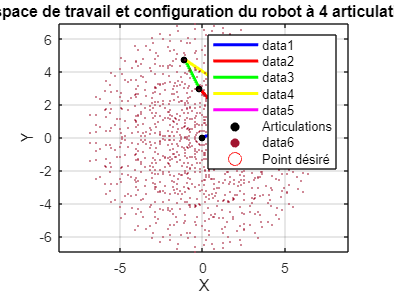

%VISUALISER LE ROBOT, LE POINT DESIRE, ET L'ESPACE DE TRAVAIL

% Calcul des positions des articulations du robot avec les valeurs des angles d'articulation calculées
O = [0, 0]; % Position de l'origine
A = [a1*cos(theta1), a1*sin(theta1)]; % Position de l'articulation A
B = A + [a2*cos(theta1+theta2), a2*sin(theta1+theta2)]; % Position de l'articulation B
C = B + [a3*cos(theta1+theta2+theta3), a3*sin(theta1+theta2+theta3)]; % Position de l'articulation C (extrémité de l'effecteur)
D = C + [a4*cos(theta1+theta2+theta3+theta4), a4*sin(theta1+theta2+theta3+theta4)]; % Position de l'articulation C (extrémité de l'effecteur)
E = D + [a5*cos(theta1+theta2+theta3+theta4+theta5), a5*sin(theta1+theta2+theta3+theta4+theta5)]; % Position de l'articulation C (extrémité de l'effecteur)

% Tracer le robot dans sa configuration actuelle
plot([O(1), A(1)], [O(2), A(2)], 'b', 'LineWidth', 2); % Segment OA
hold on;
plot([A(1), B(1)], [A(2), B(2)], 'r', 'LineWidth', 2); % Segment AB
plot([B(1), C(1)], [B(2), C(2)], 'g', 'LineWidth', 2); % Segment BC
plot([C(1), D(1)], [C(2), D(2)], 'y', 'LineWidth', 2); % Segment BC
plot([D(1), E(1)], [D(2), E(2)], 'm', 'LineWidth', 2); % Segment BC
scatter([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], 20, 'k', 'filled', 'DisplayName', 'Articulations'); % Marques pour les articulations

% Calculer les limites des axes
xlim([min(reachable_points(:, 1)), max(reachable_points(:, 1))]); ylim([min(reachable_points(:, 2)), max(reachable_points(:, 2))]);
axis equal;
title('Espace de travail et configuration du robot à 4 articulations');
xlabel('X');
ylabel('Y');
% Légende
legend;

% Tracer le nuage de points représentant l'espace de travail atteignable
scatter(reachable_points(:, 1), reachable_points(:, 2), 1, 'filled');
hold on;

% Tracer le point désiré en rouge
plot(x_desired, y_desired, 'ro', 'MarkerSize', 10, 'DisplayName', 'Point désiré');

% Affichage de la grille
grid on;

hold off; 